# Herramientas Matematicas 1

## Este es un ejemplo de publicación utilizando LiveScript.

#### Se incluyen algunos ejemplos de funciones de matlab para llevar a cabo varios cálculos. Lo importante es darse cuenta del proceso y resultado de publicación del documento

Rotaciones y sistemas de coordenadas en R2

R2 = rot2(0.3)

R2 =     0.9553   -0.2955
    0.2955    0.9553


El determinante de una matriz de rotacion es 1.

det(R2)

ans = 1.0000

El  producto de dos matrices  de rotacion es una matriz de rotacion

det(R2*R2)

ans = 1.0000

Analisis Simbolico

syms theta real
R2 = rot2(theta)

$$R2 = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

El producto de dos matrices

simplify(R2*R2)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

simplify(det(R2))

$$ans = 1$$

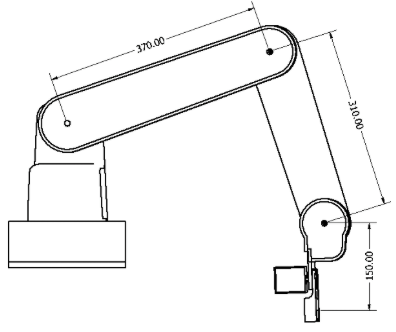

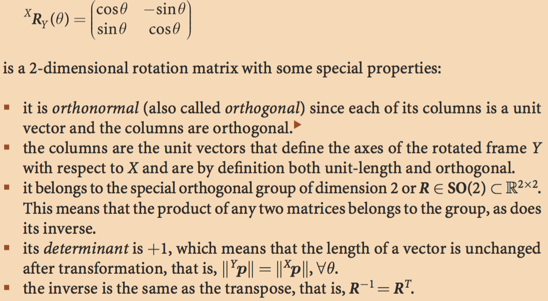

figure (1)
vec1 = [2 2]'; % Punto 1
vec2 = [3 0]'; % Punto 2
quiver(0,0,vec1(1),vec1(2),0,'r') % Vector 1
axis([-4 4 -4 4])
grid on
hold on

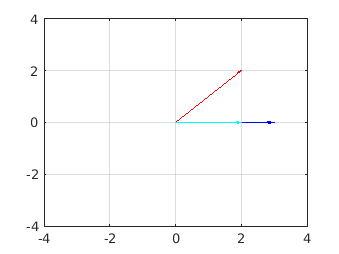


%%
quiver(0,0,vec2(1),vec2(2),0,'b') % Vector 2
%%
C_ang3 = dot(vec1,vec2)/(norm(vec1)*norm(vec2)); % Coseno del angulo
vec3 = norm(vec1)*C_ang3.*(vec2./norm(vec2)); % Proyeccion de vec1 en vec2
quiver(0,0,vec3(1),vec3(2),0,'c') 

%%
disp(strcat('Producto Escalar: ',num2str(dot(vec1,vec2))))

Producto Escalar:6


disp(strcat('Angulo entre vectores: ',num2str(acos(C_ang3)),' rad'))

Angulo entre vectores:0.7854 rad


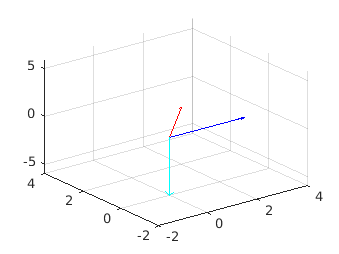

%%
vec4 = [2 2 0]'; % Punto 4
vec5 = [3 0 0]'; % Punto 5
figure (2)
quiver3(0,0,0,vec4(1),vec4(2),vec4(3),0,'r') % Vector 4
axis([-2 4 -2 4 -6 6])
grid on
hold on
%%
quiver3(0,0,0,vec5(1),vec5(2),vec5(3),0,'b') % Vector 5
%%
vec6 = cross(vec4,vec5); % Producto vectorial
%vec7 = skew(vec4)*vec5; % Producto vectorial - Skewsimetrico
quiver3(0,0,0,vec6(1),vec6(2),vec6(3),0,'m')
%%
quiver3(0,0,0,vec7(1),vec7(2),vec7(3),0,'c')

%%
disp(strcat('Producto Vectorial: ','[',num2str(vec6'),']'))

Producto Vectorial:[0  0 -6]
